DemoShearStress is a script for the initial FP2P Matlab class. The main learning objective is to develop skills in using existing pieces of Matlab code, extended with own code, to perform simulation of a part of the cardiovascular system. The secondary learning goal is to learn to interpret the data in terms of physiological regulation. 

The case is the assignment in class 1/2 of Ed on shear stress adaptation by a single blood vessel perfused by a pressure source with internal resistance. See the assignment 8: a home assignment on physiological adaptation, and the mathematical analysis in the written answer that provides the equations that you will need, notable the ones below. While there is a mathematical solution to the problem, we will simulate this model here. 

The final research questions for this assignment are: 

- Under which conditions Is an artery in a (simple) network able to adapt its diameter such that wall shear stress becomes equal to a reference value?

- How sensitive is the diameter after adaptation to a range of model parameters?

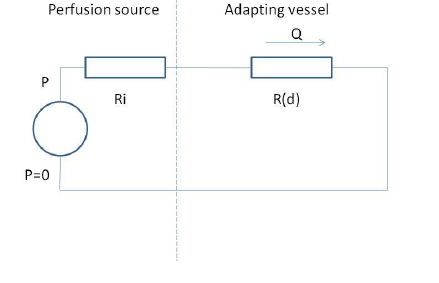

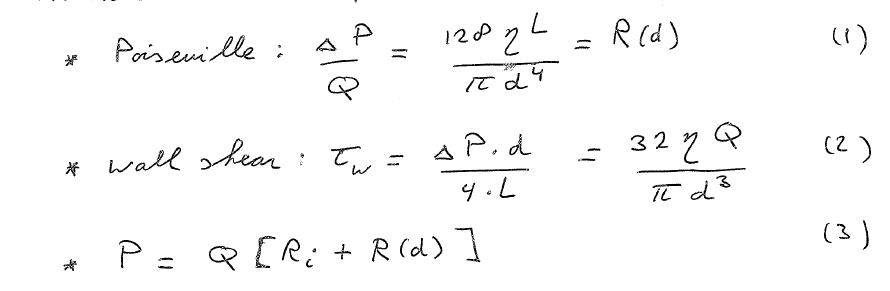

Below you will work towards answering these questions step by step. 

Let's define some model parameters: Run the section below (button above: Run Section or Ctrl+enter)

% clear previous stuff, make sure there is nothing of value in your
% workspace, and close all graphs
clear all, close all

% default model:
sourceP_nonSI=30;				% [mmHg] perfusion source pressure
sourceRi_nonSI=1e-1;			% [mL/(min*mmHg)] perfusion source internal resistance
vesselLength_nonSI=100;			% [mm] length of the adapting vessel
viscosity=1e-3;					% [Ns/m2] viscosity of the fluid
vesselDiameter_nonSI=1;			% [mm] diameter of the vessel 

STEP 1: An important issue is consistency of units. We advise to always convert units to S.I. (the exception is if the numbers get very large or small, which might lead to numerical problems, but for the problems we address today, this is not an issue.

Below, generate code to convert the model parameters to S.I.  Here, convert the model parameters to S.I. Use the suggested variable names, and follow the example for sourceRi, including the comments. Then run this section. 

We will use **{        }** for places where we expect you to fill in code, remove the { }! 



sourceP=sourceP_nonSI*133.32;						% {        } perfusion source pressure
sourceRi=sourceRi_nonSI*133/(1e-6/60) ;			% [(N/m2)/(m3/s)] perfusion source internal resistance, units expressed as a pressure divided by a flow for clarity
vesselLength=vesselLength_nonSI*1e-3;			% {        } length of the adapting vessel
vesselDiameter=vesselDiameter_nonSI*1e-3 ; 		% {        } diameter of the adapting vessel

STEP 2: We will first derive WSS in the above model as a function of the vessel diameter, where the vessel diameter is considered to be a fixed input to the model; there is no adaptation yet, only physics. You will need the above written formules, in a different order and terms left-right rearranged. While the formulas use short variable names, it is preferable to have longer names with clear meaning in your code, we indicate these names, you need to fill in the formula.  

These are the steps that you need:

- calculate the resistance of the vessel

- calculate the total resistance of this network

- calculate the flow through the vessel

- calculate the shear stress on the vessel wall

- additionally we may want to derive the pressure at the point between the source and vessel (what does this tell you?)


% use Poiseuille to calculate resistance of this vessel
vesselR=    128*(vesselLength*viscosity)/(pi*vesselDiameter^4);	% [(N/m2)/(m3/s)] vessel resistance

% total resistance is the sum of source and vessel resistance
totalR= vesselR+sourceRi    ;									% [(N/m2)/(m3/s)] total resistance

% Flow follows from pressure difference and resistance, make sure you use
% the same part of the network for pressure difference and resistance, in
% this case the whole network. 
vesselQ=  sourceP/totalR      ;									% [m3/s] flow throught the vessel, which equals flow through the source

% Local WSS follows from local flow
vesselWSS= (32* viscosity* vesselQ)/(pi * vesselDiameter^3);			% [N/m2] wall shear stress in the vessel

% calculate the pressure at the location between source and vessel
% see derivation in class of the pressure divider, based on twice ohms low
vesselPin=sourceP*vesselR/(vesselR+sourceRi);

% display the calculated WSS in the output window
disp(['vessel diameter [m]: ',num2str(vesselDiameter),'   wall shear stress [N/m2]: ',num2str(vesselWSS), '  entrance pressure vessel [N/m2]:',num2str(vesselPin) ]);

vessel diameter [m]: 0.001   wall shear stress [N/m2]: 8.3614  entrance pressure vessel [N/m2]:3344.5424


STEP 3

So far, we have assumed a single set of parameters, and calculated WSS based on the physical relations. Let us now do this exercise for a range of possible diameters: how does shear stress depend on diameter? 

A strength of Matlab is the use of vectors, helping avoiding for ... end  loops. A vector can be created by e.g. 1:3:10, meaning a vector starting at 1, each next element 3 higher, up to 10, in this case 1 4 7 10

Now make a vector of vessel diameters, from 0.05 times vesselDiameter to 3 times vesselDiameter, in steps of 0.05 times vesselDiameter


vesselDiameterv=vesselDiameter*( 0.05:0.05:3 );  


STEP 4

Matlab allows doing the calculations under step two on complete vectors, but you need to tell matlab that the calculations are piece-wise multiplications, division, power calculations rather than matrix operations. As you learned earlier, this is done by using .* ./  .^  

Meanwhile, since we will be calculating WSS a lot, let's make a function of the calculations in STEP 2

Since models can have a long array of parameters, passing all these parameters on to the function may become unreadable. A better strategy is to combine all the parameters in a structure (normally, you would do this right from the start). Therefore, below, define a structure modelPars that has as fields the model parameters, and assign the values of these model parameters to the fields. Do this for sourceP and so on, but leave out vesselDiameter or vesselDiameterv from the structure. Even though the diameter is a fixed parameter now, later on this will be a (state) variable that changes over time.  

Now make this function. In a script file like this file, the function needs to be at the end, so see below. Use the header that is defined there and fill in the  code for this function, basically that of step 2 but make sure it allows the diameter as input argument to be a vector, using  .* ./  .^  

Explain in the function code what the function takes as input, what it does and what it generates as output. Be specific! 

% define the modelPars structure and assign the values to the fields
modelPars.sourceP=sourceP;
modelPars.sourceRi=sourceRi;
modelPars.vesselLength=vesselLength;
modelPars.viscosity=viscosity;

% at the end of this file, generate the code for the function [vWSS,vPin]=calcWSS(diam,mP)  

STEP 5

Now let's run the function you made for the vector of diameters and the modelPars that you created, and make a plot of WSS and Pin as a function of the vessel diameter. Make sure you add labels to the axes, and include units in these labels. Plot both the WSS and the entrance pressure of the vessel, using subplot. Would you have the two plots arranged vertically or horizontally?  

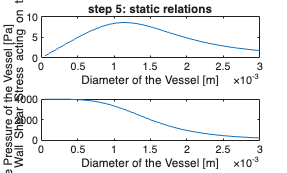

% fill in code for executing calcWSS
[vesselWSS,vesselPin]=calcWSS(vesselDiameterv,modelPars);
% plot the results
figure(5) 
subplot (2,1,1); plot( vesselDiameterv,vesselWSS); xlabel ('Diameter of the Vessel [m]'); ylabel ('Wall Shear Stress acting on the Vessel [N/m^2]'); title('step 5: static relations')
subplot (2,1,2); plot( vesselDiameterv,vesselPin); xlabel ('Diameter of the Vessel [m]'); ylabel ('Entrance Pressure of the Vessel [Pa]')

STEP 6

So far, we have created a physical model, and calculated model results of interest for a range of parameters. The model is static: for each parameter set, there is a WSS that depends algebraically on the parameters. Yet you learned that vessels are sensitive to WSS, and adapt their diameter. So let's include this biology here, and make this a dynamic model. 

The adaptation to WSS may be described by an ordinary differential equation (ODE) as follows: dD/dt= k*D*(WSS/WSSref-1), where D is the diameter, k a rate constant, and WSSref a reference value for WSS regulation.

At the end of the script, generate the code and description of the function adapt . Below, use this function to generate a plot of dD/dt as a function of the diameter. Note that we are not yet simulating the model, but rather analyzing the adaptation rule. 

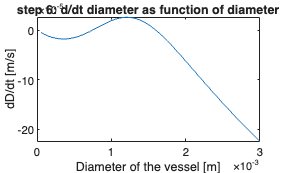

% let us first define two extra model parameters
modelPars.kadapt = 0.1;	% [] rate constant for adaptation
modelPars.WSSref = 7;		% [N/m2] reference WSS value for adaptation 

% now, at the end of the script, make a function calculating dD/dt as function of the diameter, based
% on calcWSS and this adaptation model. The header is already there

% run this function for vesselDiameterv and modelPars as input, and vesselDdot as  output 
vesselDdot=adapt([],vesselDiameterv,modelPars); % nb the first argument is time, we don't need it but the ODE solver later on requires an argument here

% generate a plot that shows dD/dt as a function of diameter for the
% vector of diameters you made above
figure(6)
plot(vesselDiameterv, vesselDdot); xlabel("Diameter of the vessel [m]"); ylabel("dD/dt [m/s]"); title('step 6: d/dt diameter as function of diameter')

Here, provide a brief explanation on the shape of this graph. At around which diameter(s) will the system be in equilibrium? 

your response: For ver smal vessels (D < 0.7 mm) the vessel shrink smaller. This happens cause WSS < WSS ref . For more medium sized vessels between diameters 0.7mm and 1.5 mm the vessels grow larger maximum dialation rate occurs around 1.3 mm. We have two unstable equilibrium points one at around 0.7 mm and another at around 1.5 mm . 

STEP 7: it is time to actually simulate this model, i.e. to analyze how the diameter evolves over time. Simulating a dynamic model described by an ordinary differential equation could be done as follows:

- define the initial state

- for a series of time steps

-     calculate the state derivative

-     calculate the new state based on the old state and the state derivative, using that S(i)=S(i-1) + (t(i)-t(i-1) * dS/dt with S the state variable. 

- after the simulation, you may (re) calculate the progression of any variables that depend algebraically on the state, without the need for looping 

We should note that this is not the best way to do this, but for now the most insightfull way. 

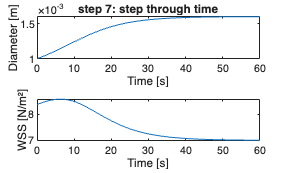

% let's first define a time step (deltat) and a vector from t=0 in steps of
% deltat s to t=60 s
deltat=0.01;	%  [s] timestep
t=0:deltat:60;   % [s] time vector

% predefine a vector for the diameter over time; while not needed this
% saves execution time since otherwise Matlab needs to find space for a
% continuously growing vector in the loop below
dynDiam=zeros(size(t));

% start with the initial value, which we will take equal to the
% vesselDiameter defined at the beginning
dynDiam(1)=vesselDiameter;

% simulate one step at a time
for it=2:length(t)
	dynDiamdot=adapt([], dynDiam(it-1), modelPars); % calculate the derivative
	dynDiam(it)=dynDiam(it-1)+deltat*dynDiamdot; % and integrate over time 
end

% let's also have the WSS over time; while we could have kept track on this
% in the loop, the WSS is a direct, algebraic function of the diameter and
% we can easily recalculate it here in one vector statement
dynWSS=calcWSS(dynDiam, modelPars); 

% plot the results in two subplots of dynDiam and dynWSS over time
figure(7)
subplot(2,1,1); plot(t, dynDiam); xlabel('Time [s]'); ylabel('Diameter [m]'); title('step 7: step through time')
subplot(2,1,2); plot(t, dynWSS); xlabel('Time [s]'); ylabel('WSS [N/m²]');

STEP 8: here we will redo the simulation of the dynamic system, but rather than looping over the time ourselves, we let Matlab decide on the time steps and the use of the derivatives to calculate progression. There are multiple ways of doing so, a common one is the second-third order runga-kutta method, implemented in matlab by the function ODE23. Below, we have set up the statement for using this method; the syntax of ode23 as used below is rather complex, take it for granted. 

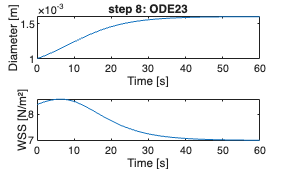

% explicitly define the initial diameter 
initVesselDiameter=vesselDiameter;

% specify the tolerance and maximal time step size of the ode23 function
options = odeset('RelTol',1e-4,'MaxStep',1);

% use the Runga-Kutta (RK) method to solve the ODE numerically
[tRK,dynDiamRK]=ode23(@(tv,dynDiamRK) adapt(tv,dynDiamRK,modelPars),[0 t(end)],initVesselDiameter,options);

% again calculate the WSS
dynWSSRK=calcWSS(dynDiamRK, modelPars); 

% and plot the results in two subplots
figure(9)
subplot(2,1,1); plot(tRK, dynDiamRK); xlabel('Time [s]'); ylabel('Diameter [m]'); title('step 8: ODE23')
subplot(2,1,2); plot(tRK, dynWSSRK); xlabel('Time [s]'); ylabel('WSS [N/m²]');

Compare the output of the two methods: any differences?

Your answer: There seems barely any difference visually.

STEP 9: investigate the model behaviour and address the research questions as were stated at the top of this file: This is the first:

- Under which conditions Is an artery in a (simple) network able to adapt its diameter such that wall shear stress becomes equal to a reference value?

A specific question is whether in steady state WSS equals its reference value and the diameter is still larger than zero. We suspect that this may depend on the initial diameter (why?). Generate code that provides the final diameter and WSS after adaptation for a range of initial diameters. Generate a table in the output screen showing the results. See the help for the table datatype. Each row needs to indicate the initial diameter and the final results of a simulation. Make a decent choice for the range of initial diameters and the number of different values you want to test, e.g. around 40 values. 

initVesselDiameterv=vesselDiameter*(0.05:0.05:2)'; % ' transposes, we need a column vector for the table

% specify the tolerance of the ode23 function
options = odeset('RelTol',1e-4,'MaxStep',1);

% predefine vectors, make them column vector as this is required for the
% table we will make
nsimul=length(initVesselDiameterv);
ssDiameters=zeros(nsimul,1); 
ssWSS=zeros(nsimul,1); 

for isimul=1:length(initVesselDiameterv)
	% run the simulation with this initial diameter
	[tRK,dynDiamRK]=ode23(@(tv,dynDiamRK) adapt(tv,dynDiamRK,modelPars),[0 t(end)],initVesselDiameterv(isimul),options);
	
	% get the last value of the diameter
	ssDiameters(isimul)=dynDiamRK(end);
	
	% calculate the associated WSS
	ssWSS(isimul)=calcWSS(ssDiameters(isimul), modelPars);
end

% define a table with the results
ssAnalysis = table(initVesselDiameterv, ssDiameters, ssWSS, 'VariableNames', {'InitialDiameter_m', 'FinalDiameter_m', 'FinalWSS_Npm2'});

STEP 10: address the second question, CONSIDER THIS AS AN EXTRA ASSIGNMENT

- How sensitive is the diameter after adaptation (i.e. in steady state) to a range of model parameters?

There are many choices to make here, your choice, but this could be an option: If there was no pressure, there would not have been flow, no WSS, and the vessel would shrink because WSS is below its reference value. So, what do you expect if the source pressure is lower? Generate code like the above that simulates the model for a range of source pressures, while in each case the vessel starts at a large diameter. Then plot the steady steate diameter and WSS as a function of the source pressure. 

sourcePv={        }'; % [ N/m2] make a column vector of possible parameter values
% start with a large diameter
initVesselDiameter=5e-3; % [m]
% and simulate a bit longer
tend=300; %[s]

% specify the tolerance of the ode23 function
options = odeset('RelTol',1e-3,'MaxStep',10);

% predefine vectors, make them column vector as this is required for the
% table we will make
nsimul={        };
ssDiameters={        }; 
ssWSS={        }; 

% use a copy of the modelPars since we will be changing the values
copyPars=modelPars;

for isimul=1:length(sourcePv)
	copyPars.sourceP=sourcePv(isimul);
	[tRK,dynDiamRK]=ode23(@(tv,dynDiamRK) adapt(tv,dynDiamRK,copyPars),[0 tend],initVesselDiameter,options);
	
	% let's make movie of all the dynamic plots
	figure(10); plot({        }); 
	{        }; {        }; title(['STEP 10,  source P [N/m2] ',num2str(copyPars.sourceP)]);
    % in this live script, redoing this plotting generates a movie, we
    % want to fix the axis limits for this reason. Fix the units, matching
    % the time vector and the span of diameters
    axis([{        }]); drawnow % drawnow makes sure the plots are made while looping, otherwise Matlab postpones this
	
	% get the last value of the diameter
	ssDiameters(isimul)={        };
	
	% calculate the associated WSS
	ssWSS(isimul)={        }; 
end
% and plot the results, indicating that this is step 10 with source P variation	
{        }


ans =

  0×0 empty cell array



FUNCTION DEFINITIONS

ad STEP 4: Below complete the function calculating WSS and the vessel entrance pressure as function of the diameter and the model parameters 

function [vWSS,vPin]=calcWSS(diam,mP)
% Calculates the Wall Shear Stress and Input Pressure over a range of diameters for a vessel 
% Usage syntax: [vWSS,vPin]=calcWSS(diam, mP); 
% Inputs:
%   diam - vessel diameter [m]
%   mP   - structure with model parameters:
%          mP.sourceP  : perfusion source pressure [Pa]
%          mP.sourceRi : source internal resistance [Pa.s/m^3]
%          mP.vesselLength : vessel length [m]
%          mP.viscosity    : fluid viscosity [Pa.s]
%
% Outputs:
%   vWSS - wall shear stress [N/m^2] corresponding to each diameter
%   vPin - pressure at the entrance of the vessel [Pa]


% use Poiseuille to calculate resistance of this vessel, copy the statement
% you formulated earlier but make sure it will now allow vectors for
% diameter
vesselR=128 * mP.viscosity * mP.vesselLength ./(pi .* diam.^4) ;		% [(N/m2)/(m3/s)] vessel resistance

% total resistance is the sum of source and vessel resistance
totalR=mP.sourceRi + vesselR;										% [(N/m2)/(m3/s)] total resistance

% Flow follows from pressure difference and resistance, make sure you use
% the same part of the network for pressure difference and resistance, in
% this case the whole network. 
vesselQ=mP.sourceP ./ totalR;									% [m3/s] flow throught the vessel, which equals flow through the source

% Local WSS follows from local flow
vWSS= 32*mP.viscosity .*vesselQ ./ (pi.*diam.^3);			% [N/m2] wall shear stress in the vessel

% calculate the pressure between source and vessel
% see derivation in class, based on twice ohms low
vPin=mP.sourceP .*vesselR./totalR;
end

ad STEP 6: Below complete the function calculating the time derivative of the diameter as a function  of time, diameter and model parameters. Note: time does not play a role here, but needs to be defined as the first input argument for the ODE23 function

function vDdot=adapt(t,vD,mP)
% compute the rate of change of vessel diameter with respect to time  
% Inputs : 
%    t - time[sec]
%   vD - vessel diameter at this point in time [m]
%   mP - model parameters
% Outputs :
%   vDdot - time derivative of the diameter [m/s]
% dD/dt= k*D*(WSS/WSSref-1)
% Current wall shear stress
[vWSS,~]=calcWSS(vD,mP); 
% time derivative of the vessel diameter 
vDdot= mP.kadapt .* vD .* (vWSS./mP.WSSref -1);
end